# Tutorial 7

## Euler's Method related to the Python(exercise 1.b)   

% define the y' = f(x,y) f = t^2+1
f = @(t,y)t^2+0*y+1;
% initial values
t0 = 1;
y0 = 4;
h = 0.5;
% find the predicted value of x
tx = 2;
[t,y] = odeEuler(f,[t0,tx],y0,h);

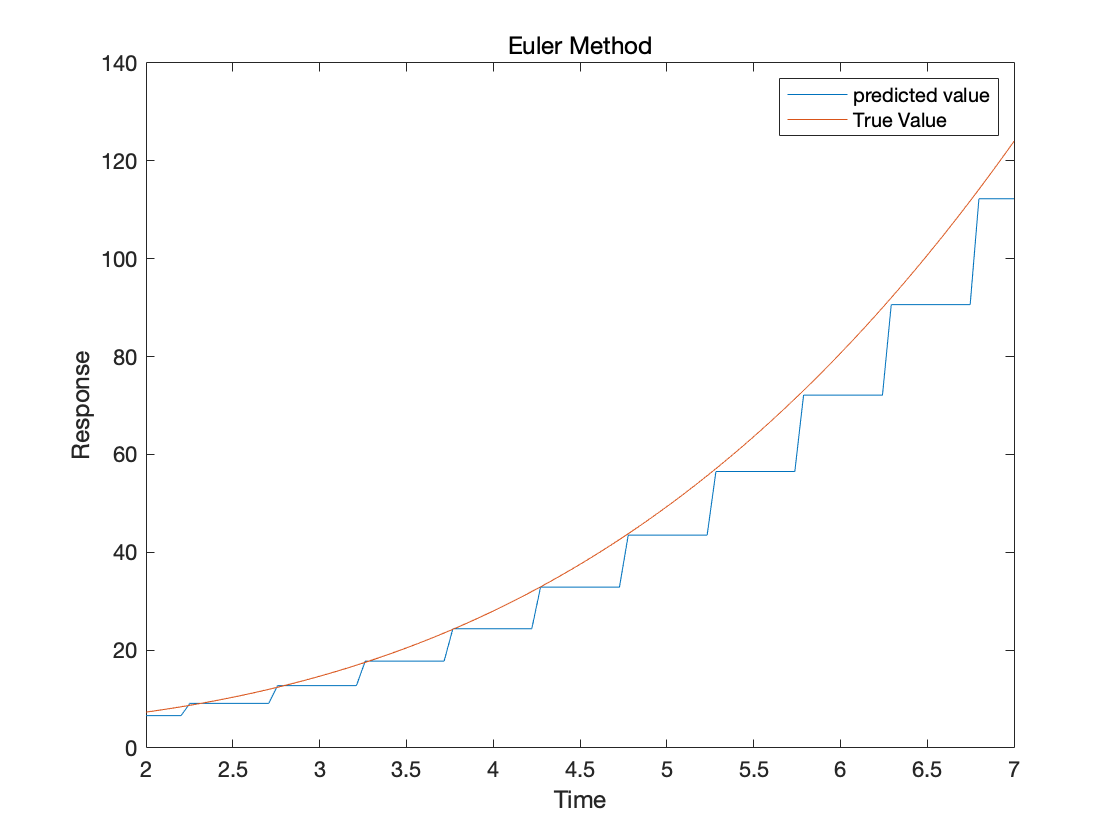

% find the continuous value of y
ts = linspace(2,7,100);
l = length(ts);
ys = zeros(l,1);
for i = 1:1:l
    [t,yx] = odeEuler(f,[t0,ts(i)],y0,h);
    ys(i) = yx(end);
end
yture = ts.^3/3+ts+8/3;
plot(ts,ys,ts,yture);
xlabel('Time')
ylabel('Response')
legend('predicted value','True Value')
title('Euler Method')

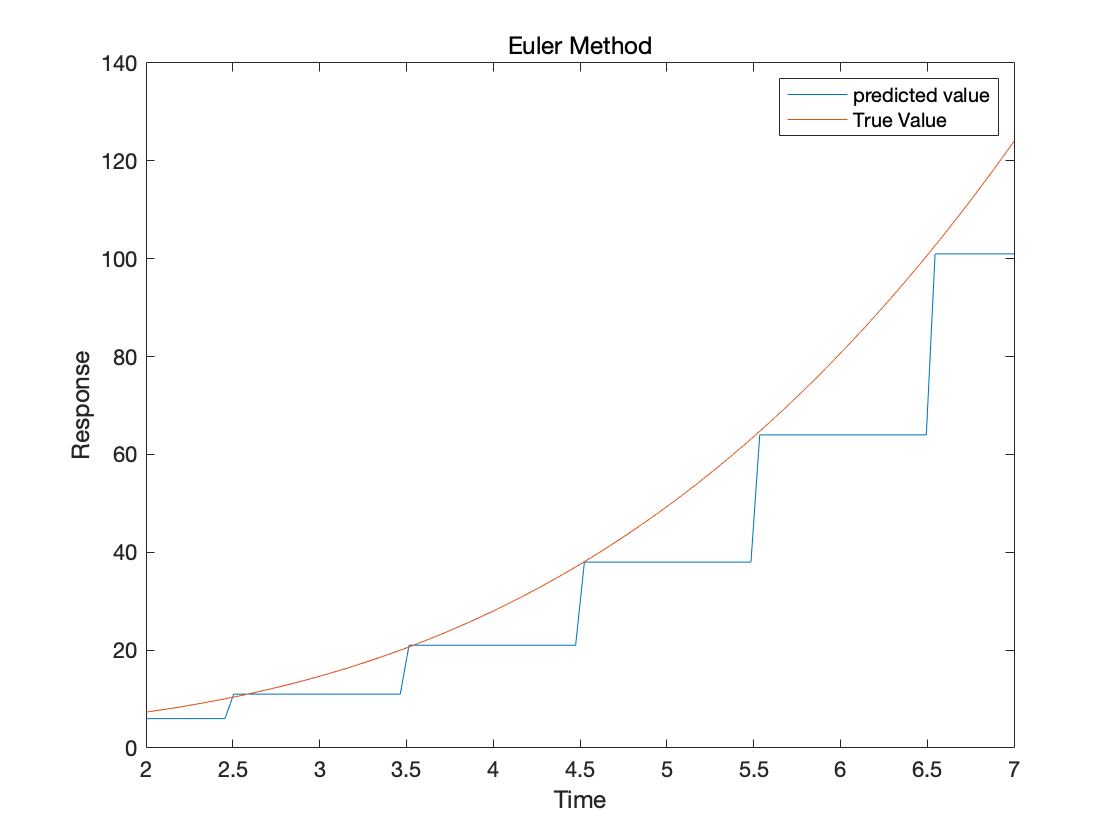

h = 1;
% find the continuous value of y
ts = linspace(2,7,100);
l = length(ts);
ys = zeros(l,1);
for i = 1:1:l
    [t,yx] = odeEuler(f,[t0,ts(i)],y0,h);
    ys(i) = yx(end);
end
yture = ts.^3/3+ts+8/3;
plot(ts,ys,ts,yture);
xlabel('Time')
ylabel('Response')
legend('predicted value','True Value')
title('Euler Method')

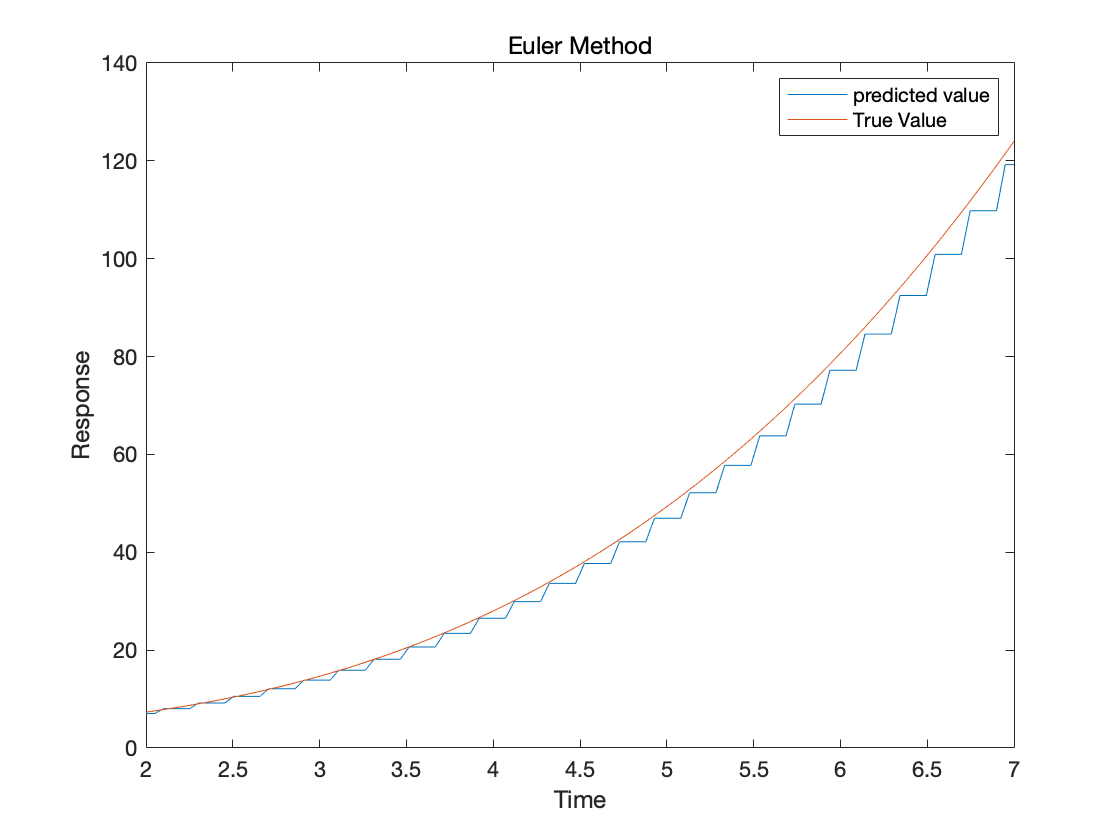

h = 0.2;
[t,y] = odeEuler(f,[t0,tx],y0,h);
% find the continuous value of y
ts = linspace(2,7,100);
l = length(ts);
ys = zeros(l,1);
for i = 1:1:l
    [t,yx] = odeEuler(f,[t0,ts(i)],y0,h);
    ys(i) = yx(end);
end
yture = ts.^3/3+ts+8/3;
plot(ts,ys,ts,yture);
xlabel('Time')
ylabel('Response')
legend('predicted value','True Value')
title('Euler Method')

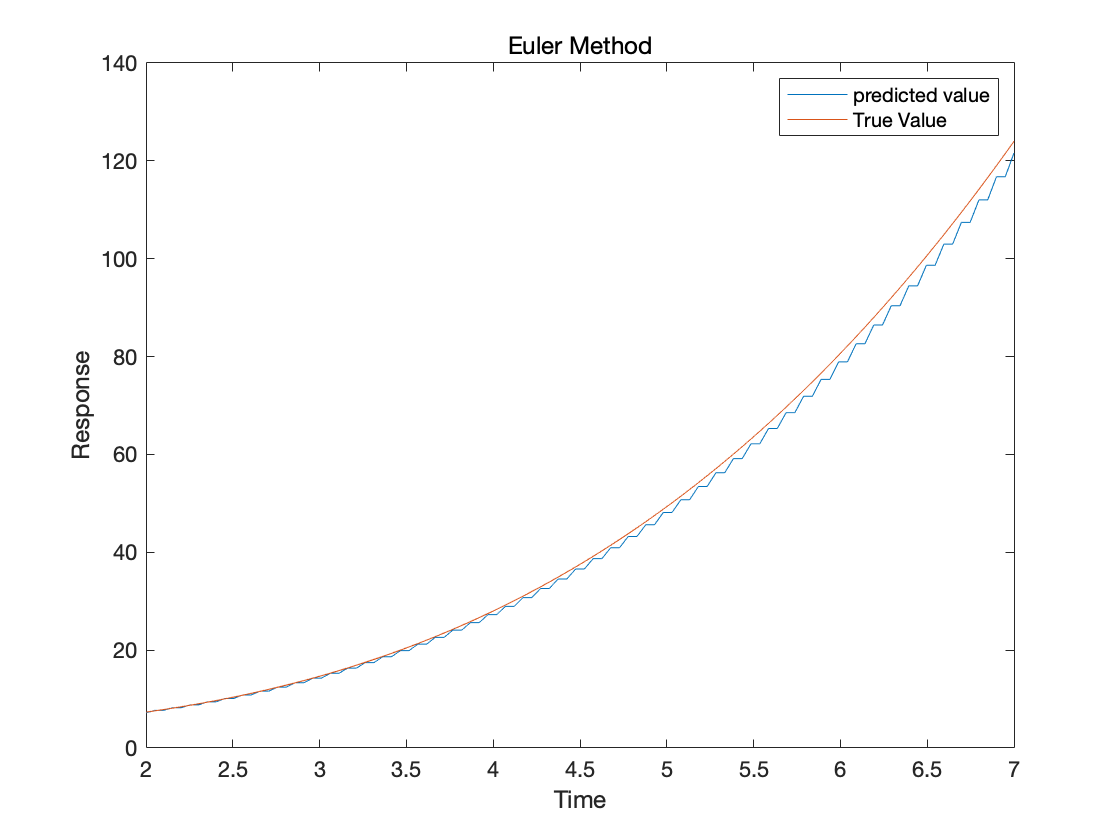

h = 0.1;
[t,y] = odeEuler(f,[t0,tx],y0,h);
% find the continuous value of y
ts = linspace(2,7,100);
l = length(ts);
ys = zeros(l,1);
for i = 1:1:l
    [t,yx] = odeEuler(f,[t0,ts(i)],y0,h);
    ys(i) = yx(end);
end
yture = ts.^3/3+ts+8/3;
plot(ts,ys,ts,yture);
xlabel('Time')
ylabel('Response')
legend('predicted value','True Value')
title('Euler Method')

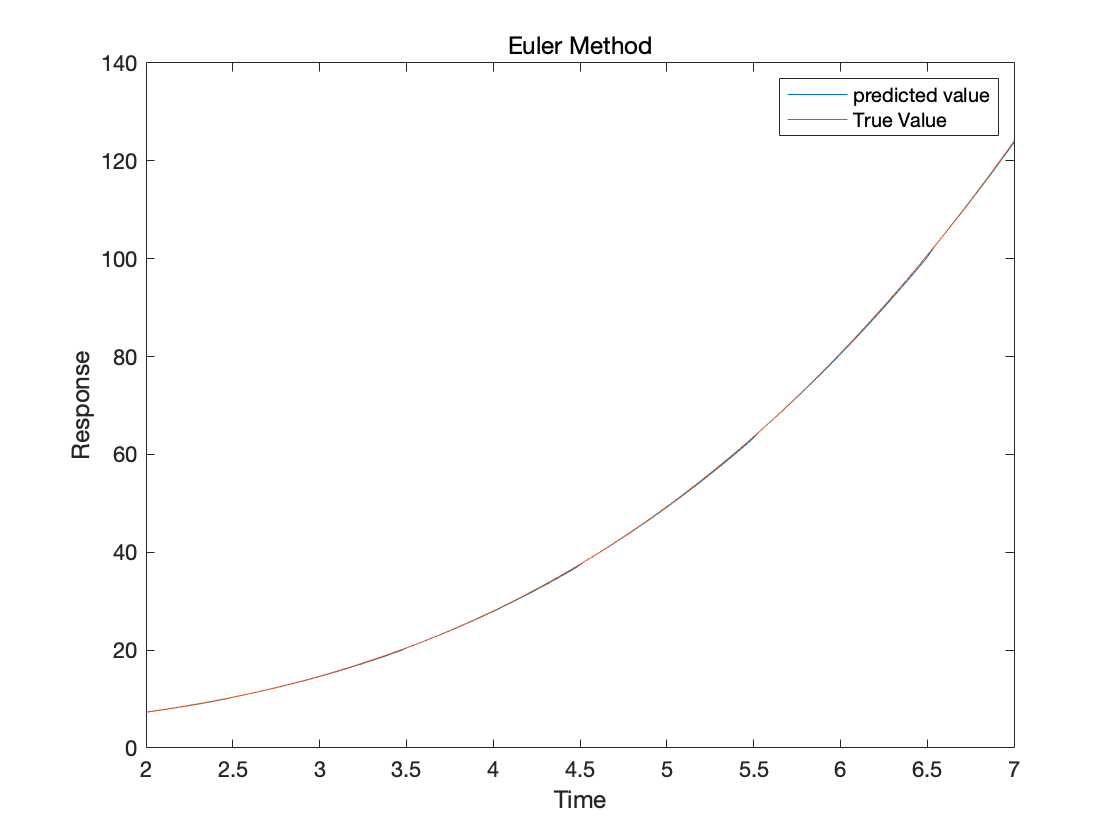

h = 0.01;
[t,y] = odeEuler(f,[t0,tx],y0,h);
% find the continuous value of y
ts = linspace(2,7,100);
l = length(ts);
ys = zeros(l,1);
for i = 1:1:l
    [t,yx] = odeEuler(f,[t0,ts(i)],y0,h);
    ys(i) = yx(end);
end
yture = ts.^3/3+ts+8/3;
plot(ts,ys,ts,yture);
xlabel('Time')
ylabel('Response')
legend('predicted value','True Value')
title('Euler Method')

## Exercise 1.a

% define the function
f1 = @(t,y)0*t+3*y;
t0 = 0;
y0 = 2;
nstep = 2;
h = 0.1;
ts = h * nstep +t0;
[tt,yy] = odeEuler(f1,[t0,ts],y0,h);

## Exercise 1.c

% define the function
f3 = @(t,y)log(t)+0*y;
t0 = 1;
y0 = 0;
h = 1;
nstep = 2;
ts = h * nstep +t0;
[tt,yy] = odeEuler(f3,[t0,ts],y0,h);

## Exercise 2

% define the function
f3_true = @(t,y)t*log(t)-t+1;
f3 = @(t,y)log(t)+0*y;
t0 = 1;
y0 = 0;
h = 1;
nstep = 2;
% ts = h * nstep +t0;
f3_value = feval(f3_true,2,0);
pre_value = 1e4;
while (abs(pre_value-f3_value)>0.05)
    [tt,yy] = odeEuler(f3,[t0,2],y0,h);
    pre_value = yy(end);
    h = h - 0.1;
end
print_value = 'The predicted value is %0.6f\nh is %0.6e';
sprintf(print_value,pre_value,h)

ans =     'The predicted value is 0.351221
     h is 1.387779e-16'
